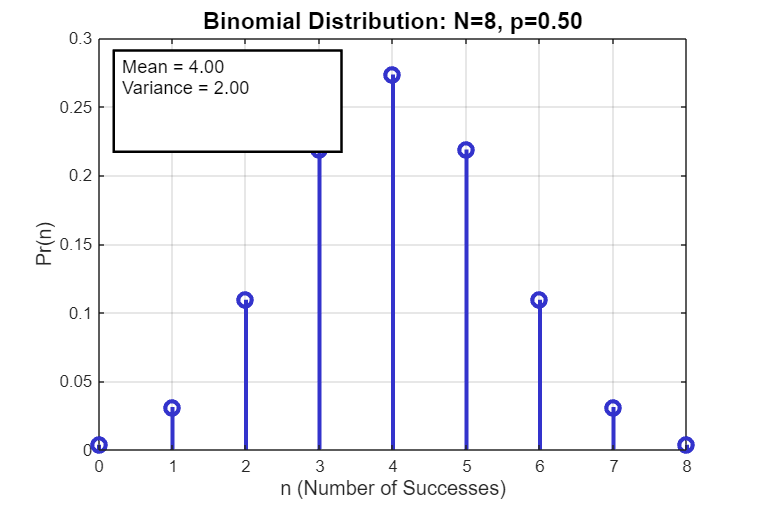

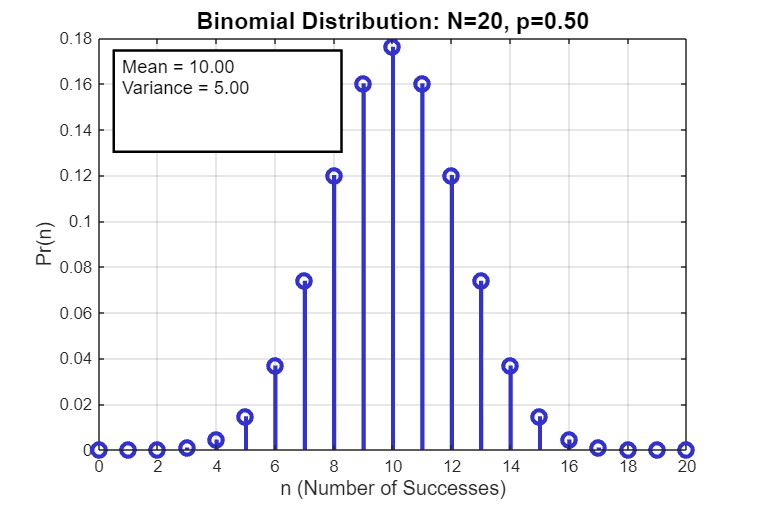

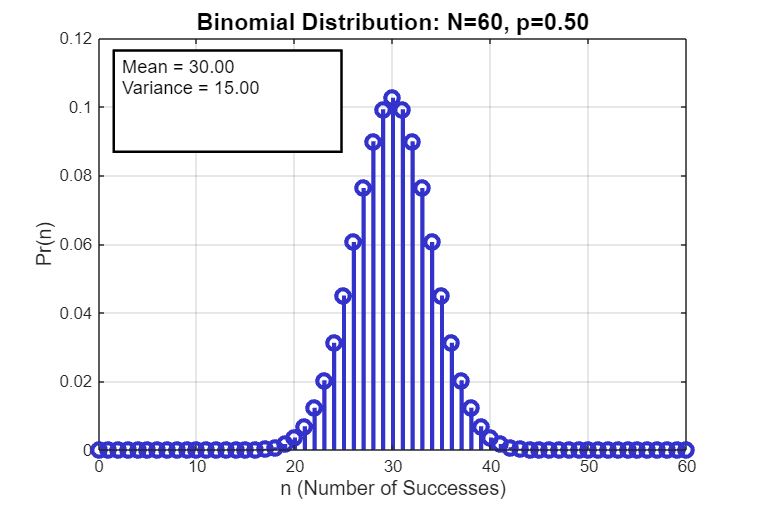

% OPTI 512L
% LAB 11
% Mohanbabu Mani

% 1.


mean_values = [4, 10, 30];

for idx = 1:length(mean_values)
    mu = mean_values(idx);
    N_binom = 2*mu;
    p_binom = 0.5;
    n_binom = 0:N_binom;
    Pr_binom = binopdf(n_binom, N_binom, p_binom);
    
    figure('Position', [100 + idx*50, 100 + idx*50, 900, 600]);
    stem(n_binom, Pr_binom, 'LineWidth', 2.5, 'MarkerSize', 8, 'Color', [0.2 0.2 0.8]);
    title(sprintf('Binomial Distribution: N=%d, p=%.2f', N_binom, p_binom), ...
        'FontSize', 14, 'FontWeight', 'bold');
    xlabel('n (Number of Successes)', 'FontSize', 12);
    ylabel('Pr(n)', 'FontSize', 12);
    grid on;
    box on;
 
    mean_binom = N_binom * p_binom;
    var_binom = N_binom * p_binom * (1 - p_binom);
    annotation('textbox', [0.15 0.7 0.3 0.2], 'String', ...
        sprintf('Mean = %.2f\nVariance = %.2f', mean_binom, var_binom), ...
        'FontSize', 11, 'BackgroundColor', 'white', 'EdgeColor', 'black', 'LineWidth', 1.5);
end

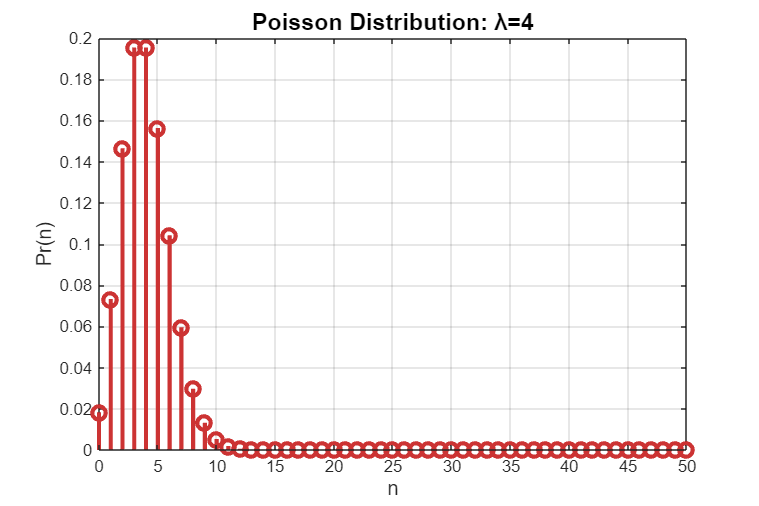

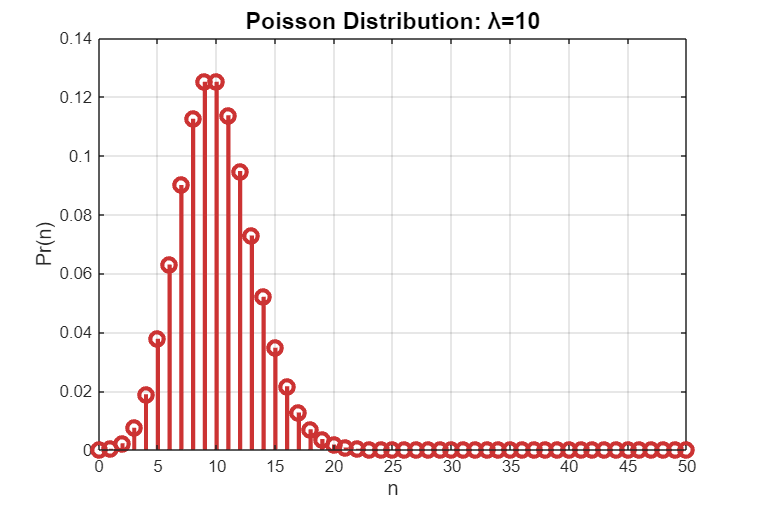

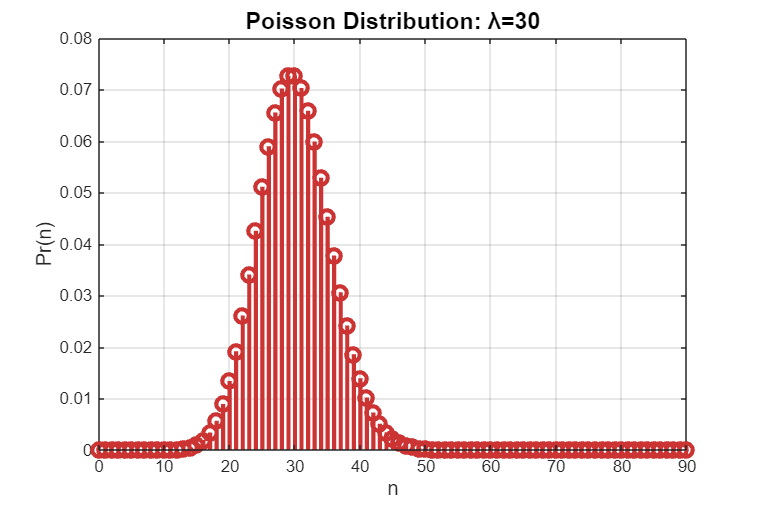



for idx = 1:length(mean_values)
    mu = mean_values(idx);
    a_poisson = mu;
    n_poisson = 0:max(50, 3*mu);
    Pr_poisson = exp(-a_poisson) .* (a_poisson.^n_poisson) ./ factorial(n_poisson);
    
    figure('Position', [100 + idx*50, 700 + idx*50, 900, 600]);
    stem(n_poisson, Pr_poisson, 'LineWidth', 2.5, 'MarkerSize', 8, 'Color', [0.8 0.2 0.2]);
    title(sprintf('Poisson Distribution: λ=%d', a_poisson), ...
        'FontSize', 14, 'FontWeight', 'bold');
    xlabel('n', 'FontSize', 12);
    ylabel('Pr(n)', 'FontSize', 12);
    grid on;
    box on;

end

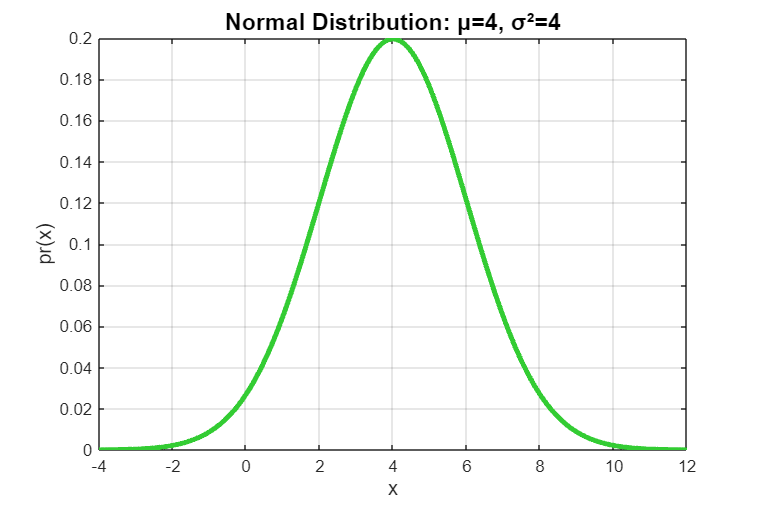

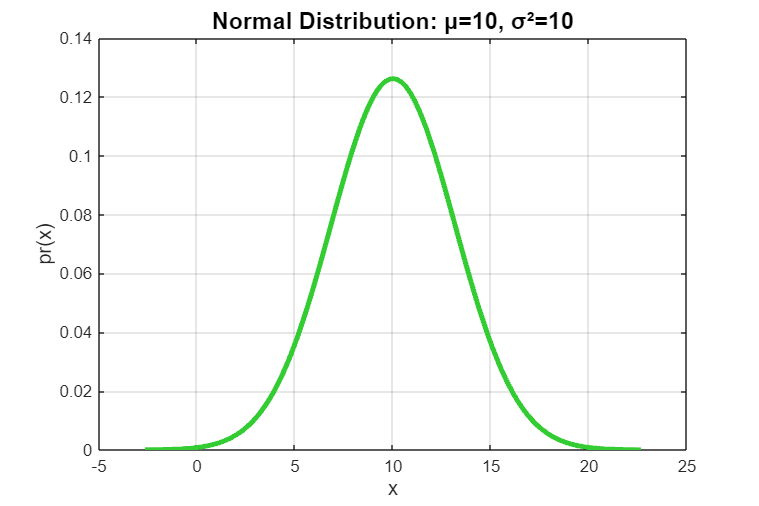

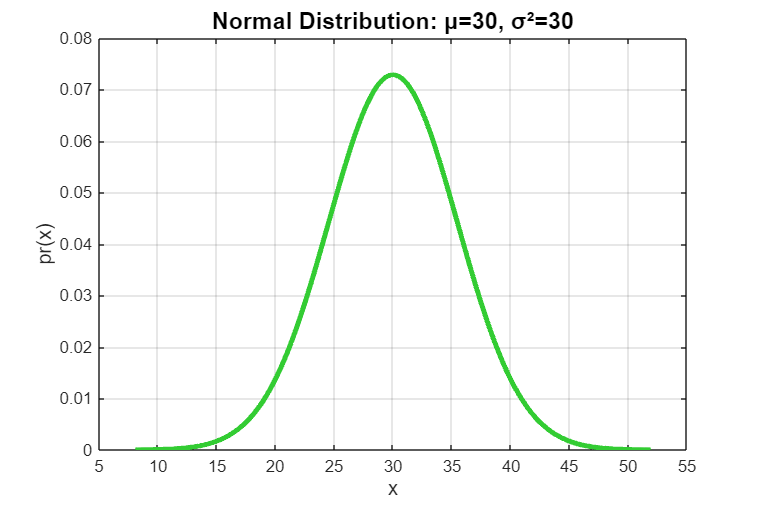


for idx = 1:length(mean_values)
    mu = mean_values(idx);
    sigma2 = mu;
    sigma = sqrt(sigma2);
    x_normal = linspace(mu - 4*sigma, mu + 4*sigma, 1000);
    pr_normal = (1/(sqrt(2*pi*sigma2))) .* exp(-(x_normal - mu).^2 / (2*sigma2));
    
    figure('Position', [100 + idx*50, 1300 + idx*50, 900, 600]);
    plot(x_normal, pr_normal, 'LineWidth', 3, 'Color', [0.2 0.8 0.2]);
    title(sprintf('Normal Distribution: μ=%d, σ²=%d', mu, sigma2), ...
        'FontSize', 14, 'FontWeight', 'bold');
    xlabel('x', 'FontSize', 12);
    ylabel('pr(x)', 'FontSize', 12);
    grid on;
    box on;
end

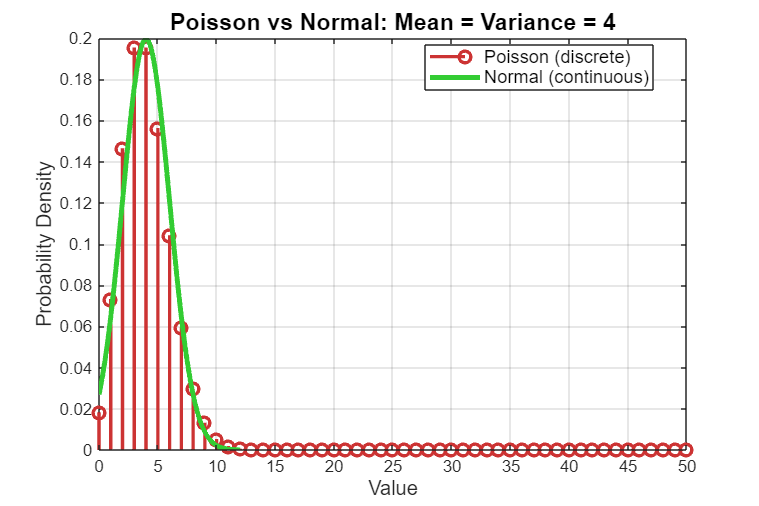

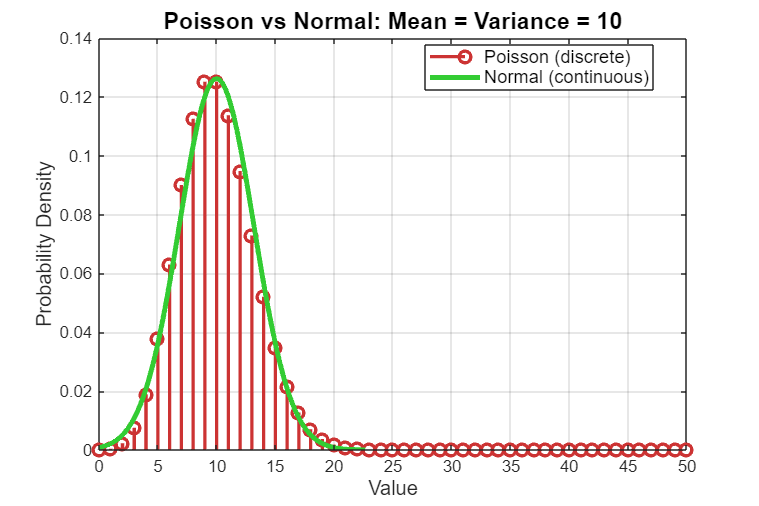

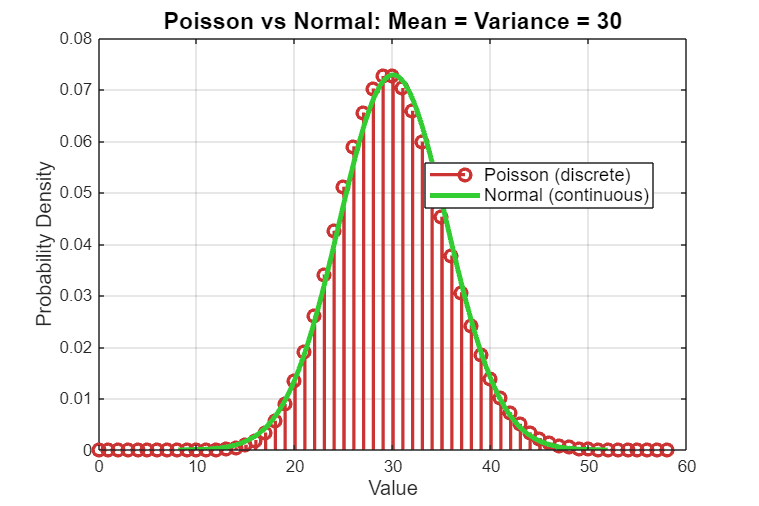



for idx = 1:length(mean_values)
    mu = mean_values(idx);
    sigma = sqrt(mu);
    n_max = max(50, ceil(mu + 5*sigma));
    n_poisson = 0:n_max;
    Pr_poisson = exp(-mu) .* (mu.^n_poisson) ./ factorial(n_poisson);
    
    x_normal = linspace(max(0, mu - 4*sigma), mu + 4*sigma, 1000);
    pr_normal = (1/(sqrt(2*pi*mu))) .* exp(-(x_normal - mu).^2 / (2*mu));
    
    figure('Position', [100 + idx*50, 1900 + idx*50, 900, 600]);
    
    stem(n_poisson, Pr_poisson, 'LineWidth', 2, 'MarkerSize', 7, 'Color', [0.8 0.2 0.2]);
    hold on;
   
    plot(x_normal, pr_normal, 'LineWidth', 3, 'Color', [0.2 0.8 0.2]);
    
    title(sprintf('Poisson vs Normal: Mean = Variance = %d', mu), ...
        'FontSize', 14, 'FontWeight', 'bold');
    xlabel('Value', 'FontSize', 12);
    ylabel('Probability Density', 'FontSize', 12);
    legend('Poisson (discrete)', 'Normal (continuous)', 'FontSize', 11, 'Location', 'best');
    grid on;
    box on;
    hold off;
    
    skewness_poisson = 1/sqrt(mu);
    
end


for idx = 1:length(mean_values)
    mu = mean_values(idx);
    sigma = sqrt(mu);
    skewness_poisson = 1/sqrt(mu);
end

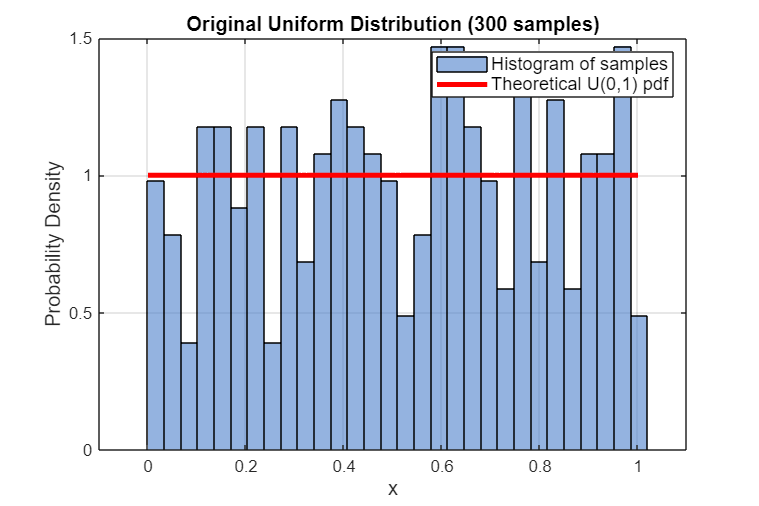

% 2.


num_samples = 300;     
N_values = [2, 5, 20]; 
x_uniform = rand(1, num_samples);

figure('Position', [100, 100, 900, 600]);
histogram(x_uniform, 30, 'Normalization', 'pdf', 'FaceColor', [0.3 0.5 0.8], 'EdgeColor', 'black');
hold on;

x_theory = linspace(0, 1, 100);
y_theory = ones(size(x_theory));  
plot(x_theory, y_theory, 'r-', 'LineWidth', 3);

title('Original Uniform Distribution (300 samples)', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 12);
ylabel('Probability Density', 'FontSize', 12);
legend('Histogram of samples', 'Theoretical U(0,1) pdf', 'FontSize', 11);
grid on;
box on;
xlim([-0.1, 1.1]);

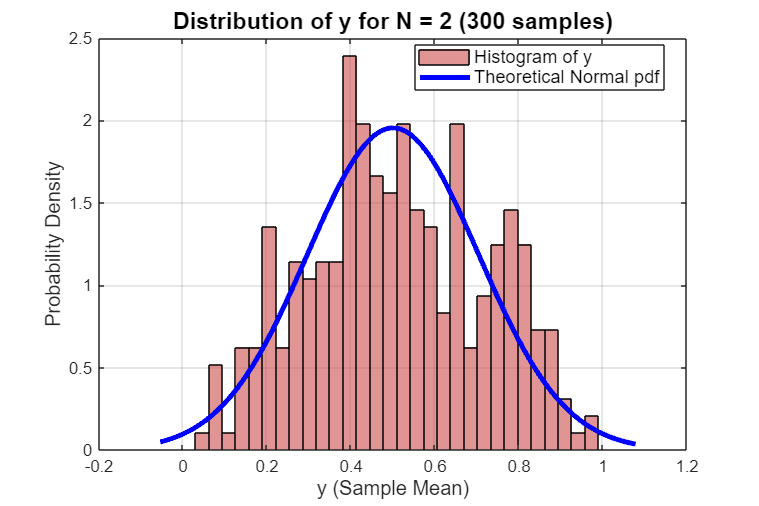

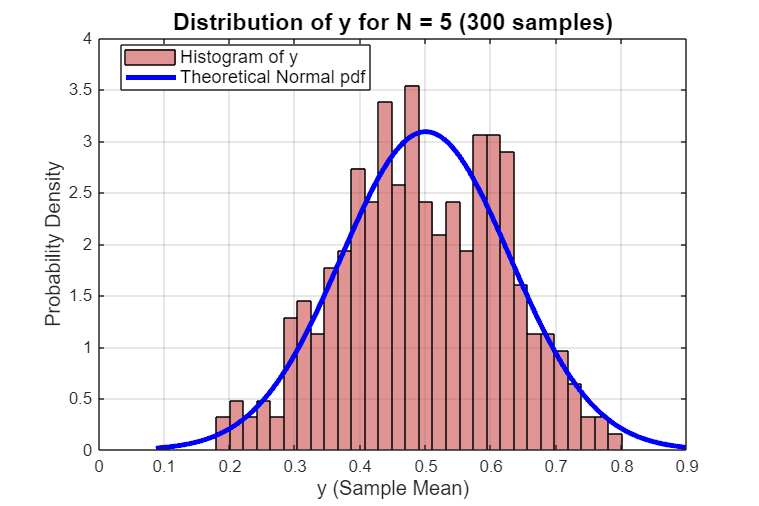

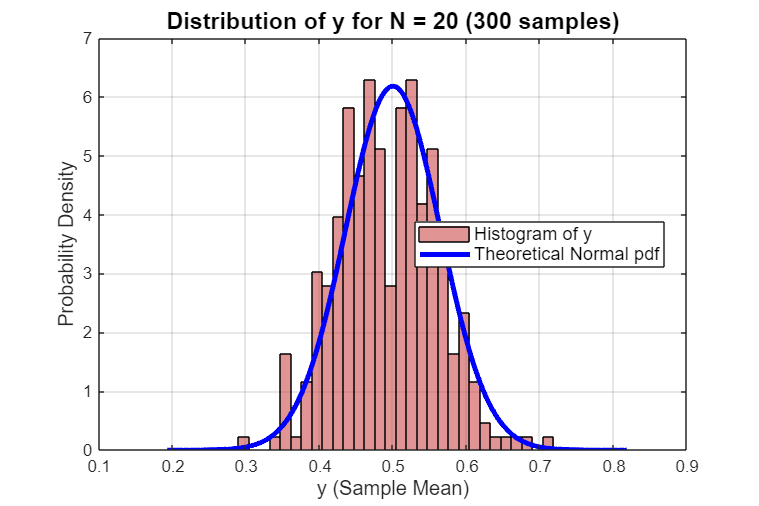

mean_x = mean(x_uniform);
var_x = var(x_uniform);

for idx = 1:length(N_values)
    N = N_values(idx);
    X = rand(N, num_samples);
    y = mean(X, 1); 
    mean_y = mean(y);
    var_y = var(y);
    theoretical_mean = 0.5;
    theoretical_var = (1/12) / N;
    theoretical_std = sqrt(theoretical_var);
    
    figure('Position', [100 + idx*80, 100 + idx*80, 900, 600]);
    histogram(y, 30, 'Normalization', 'pdf', 'FaceColor', [0.8 0.3 0.3], 'EdgeColor', 'black');
    hold on;
    
    x_range = linspace(min(y)-0.1, max(y)+0.1, 1000);
    normal_pdf = (1/(sqrt(2*pi*theoretical_var))) * ...
                 exp(-(x_range - theoretical_mean).^2 / (2*theoretical_var));
    plot(x_range, normal_pdf, 'b-', 'LineWidth', 3);
    
    title(sprintf('Distribution of y for N = %d (300 samples)', N), ...
          'FontSize', 14, 'FontWeight', 'bold');
    xlabel('y (Sample Mean)', 'FontSize', 12);
    ylabel('Probability Density', 'FontSize', 12);
    legend('Histogram of y', 'Theoretical Normal pdf', 'FontSize', 11, 'Location', 'best');
    grid on;
    box on;
end

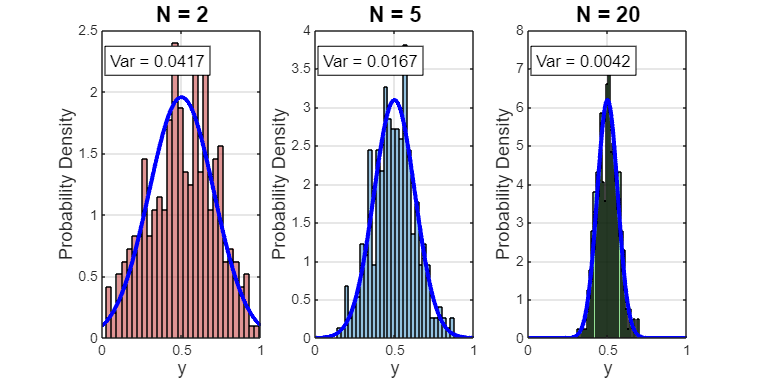


figure('Position', [200, 200, 1200, 600]);

colors = {[0.8 0.3 0.3], [0.3 0.6 0.8], [0.3 0.8 0.3]};

for idx = 1:length(N_values)
    N = N_values(idx);
    X = rand(N, num_samples);
    y = mean(X, 1);

    theoretical_mean = 0.5;
    theoretical_var = (1/12) / N;

    subplot(1, 3, idx);
    
    histogram(y, 30, 'Normalization', 'pdf', 'FaceColor', colors{idx}, 'EdgeColor', 'black');
    hold on;
    
    x_range = linspace(0, 1, 1000);
    normal_pdf = (1/(sqrt(2*pi*theoretical_var))) * ...
                 exp(-(x_range - theoretical_mean).^2 / (2*theoretical_var));
    plot(x_range, normal_pdf, 'b-', 'LineWidth', 2.5);
    
    title(sprintf('N = %d', N), 'FontSize', 13, 'FontWeight', 'bold');
    xlabel('y', 'FontSize', 11);
    ylabel('Probability Density', 'FontSize', 11);
    xlim([0, 1]);
    grid on;
    box on;
    
    text(0.05, max(ylim)*0.9, sprintf('Var = %.4f', theoretical_var), ...
         'FontSize', 10, 'BackgroundColor', 'white', 'EdgeColor', 'black');
    hold off;
end

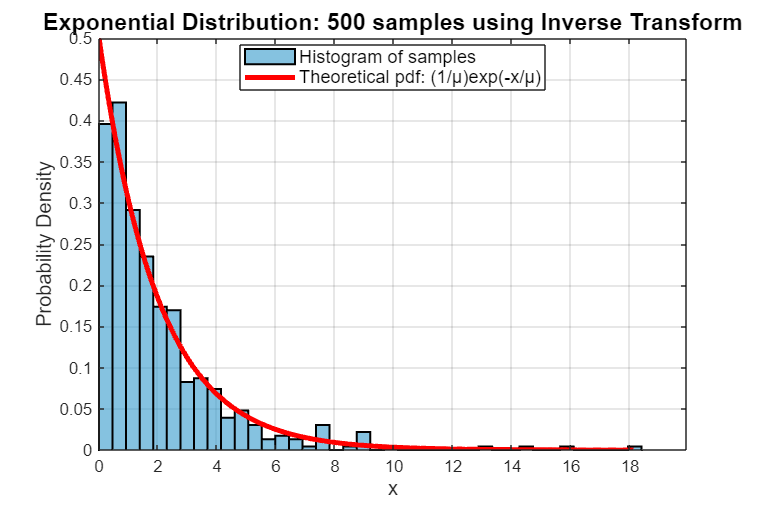

% 3.


num_samples = 500;
mu_exp = 2; 
U_exp = rand(1, num_samples); 
X_exp = -mu_exp * log(U_exp);   

mean_exp = mean(X_exp);
var_exp = var(X_exp);
std_exp = std(X_exp);

figure('Position', [100, 100, 900, 600]);
histogram(X_exp, 40, 'Normalization', 'pdf', 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'black', 'LineWidth', 1.2);
hold on;

x_exp_theory = linspace(0, max(X_exp), 500);
pr_exp_theory = (1/mu_exp) * exp(-x_exp_theory / mu_exp);
plot(x_exp_theory, pr_exp_theory, 'r-', 'LineWidth', 3);

title('Exponential Distribution: 500 samples using Inverse Transform', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 12);
ylabel('Probability Density', 'FontSize', 12);
legend('Histogram of samples', 'Theoretical pdf: (1/μ)exp(-x/μ)', 'FontSize', 11, 'Location', 'best');
grid on;
box on;
xlim([0, max(X_exp)*1.1]);

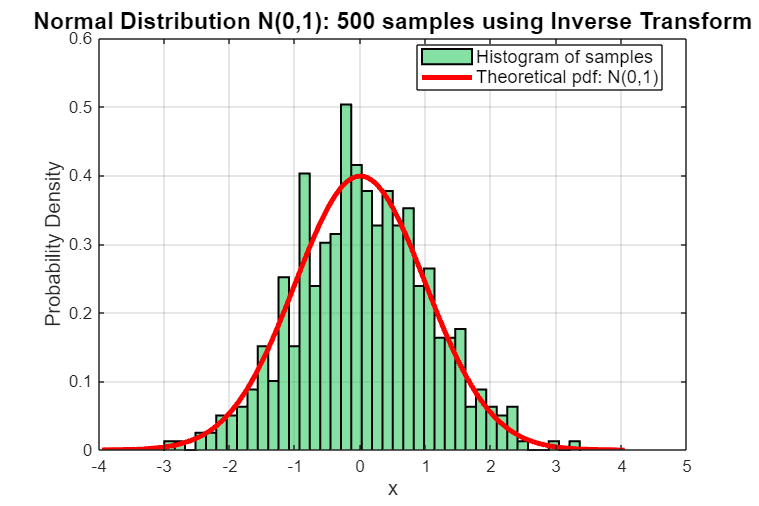


mu_norm = 0;     
sigma_norm = 1;   
U_norm = rand(1, num_samples);

Z_norm = sqrt(2) * erfinv(2*U_norm - 1);
X_norm = mu_norm + sigma_norm * Z_norm;
mean_norm = mean(X_norm);
var_norm = var(X_norm);
std_norm = std(X_norm);

figure('Position', [100, 700, 900, 600]);
histogram(X_norm, 40, 'Normalization', 'pdf', 'FaceColor', [0.2 0.8 0.4], 'EdgeColor', 'black', 'LineWidth', 1.2);
hold on;

x_norm_theory = linspace(mean_norm - 4*sigma_norm, mean_norm + 4*sigma_norm, 500);
pr_norm_theory = (1/(sigma_norm*sqrt(2*pi))) * exp(-(x_norm_theory - mu_norm).^2 / (2*sigma_norm^2));
plot(x_norm_theory, pr_norm_theory, 'r-', 'LineWidth', 3);

title('Normal Distribution N(0,1): 500 samples using Inverse Transform', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 12);
ylabel('Probability Density', 'FontSize', 12);
legend('Histogram of samples', 'Theoretical pdf: N(0,1)', 'FontSize', 11, 'Location', 'best');
grid on;
box on;

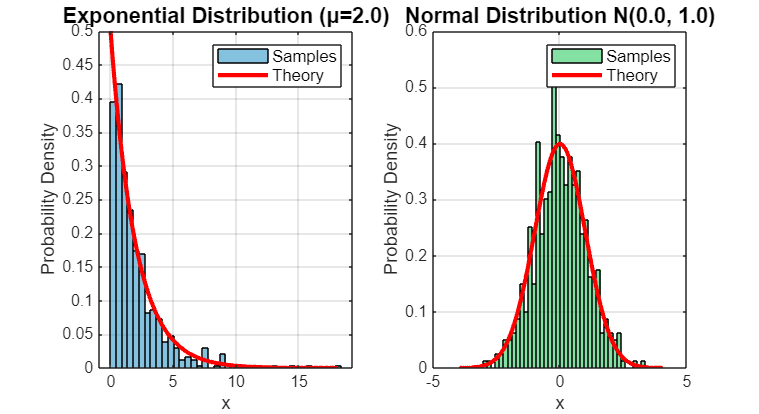


figure('Position', [100, 1350, 1100, 600]);

subplot(1, 2, 1);
histogram(X_exp, 40, 'Normalization', 'pdf', 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'black');
hold on;
x_exp_theory = linspace(0, max(X_exp), 500);
pr_exp_theory = (1/mu_exp) * exp(-x_exp_theory / mu_exp);
plot(x_exp_theory, pr_exp_theory, 'r-', 'LineWidth', 2.5);
title(sprintf('Exponential Distribution (μ=%.1f)', mu_exp), 'FontSize', 13, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 11);
ylabel('Probability Density', 'FontSize', 11);
legend('Samples', 'Theory', 'FontSize', 10);
grid on;
box on;
hold off;

subplot(1, 2, 2);
histogram(X_norm, 40, 'Normalization', 'pdf', 'FaceColor', [0.2 0.8 0.4], 'EdgeColor', 'black');
hold on;
x_norm_theory = linspace(mean_norm - 4*sigma_norm, mean_norm + 4*sigma_norm, 500);
pr_norm_theory = (1/(sigma_norm*sqrt(2*pi))) * exp(-(x_norm_theory - mu_norm).^2 / (2*sigma_norm^2));
plot(x_norm_theory, pr_norm_theory, 'r-', 'LineWidth', 2.5);
title(sprintf('Normal Distribution N(%.1f, %.1f)', mu_norm, sigma_norm^2), 'FontSize', 13, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 11);
ylabel('Probability Density', 'FontSize', 11);
legend('Samples', 'Theory', 'FontSize', 10);
grid on;
box on;
hold off;

% 4.

mu_true = 3.5;  
N = 100;
U = rand(1, N);
V = -mu_true * log(U);

fprintf('  ');

for i = 1:10
    fprintf('%.3f  ', V(i));
end

0.985  0.554  0.387  1.413  7.222  4.541  1.023  2.849  3.801  1.959  

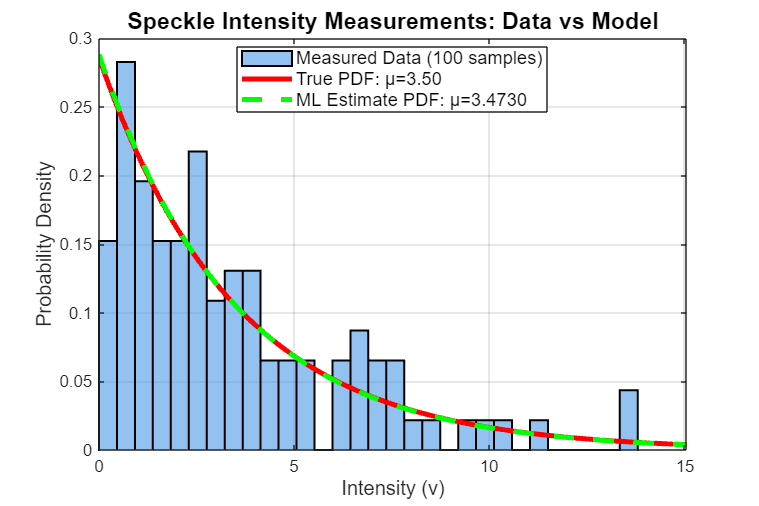


mu_ML = mean(V);

mu_sample = mean(V);
sigma_sample = std(V);
var_sample = var(V);

figure('Position', [100, 100, 900, 600]);
histogram(V, 30, 'Normalization', 'pdf', 'FaceColor', [0.3 0.6 0.9], ...
    'EdgeColor', 'black', 'LineWidth', 1.2);
hold on;
v_range = linspace(0, max(V)*1.2, 500);
pr_true = (1/mu_true) * exp(-v_range / mu_true);
plot(v_range, pr_true, 'r-', 'LineWidth', 3);
pr_ML = (1/mu_ML) * exp(-v_range / mu_ML);
plot(v_range, pr_ML, 'g--', 'LineWidth', 3);

title('Speckle Intensity Measurements: Data vs Model', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Intensity (v)', 'FontSize', 12);
ylabel('Probability Density', 'FontSize', 12);
legend('Measured Data (100 samples)', ...
    sprintf('True PDF: μ=%.2f', mu_true), ...
    sprintf('ML Estimate PDF: μ=%.4f', mu_ML), ...
    'FontSize', 11, 'Location', 'best');
grid on;
box on;
xlim([0, max(V)*1.1]);

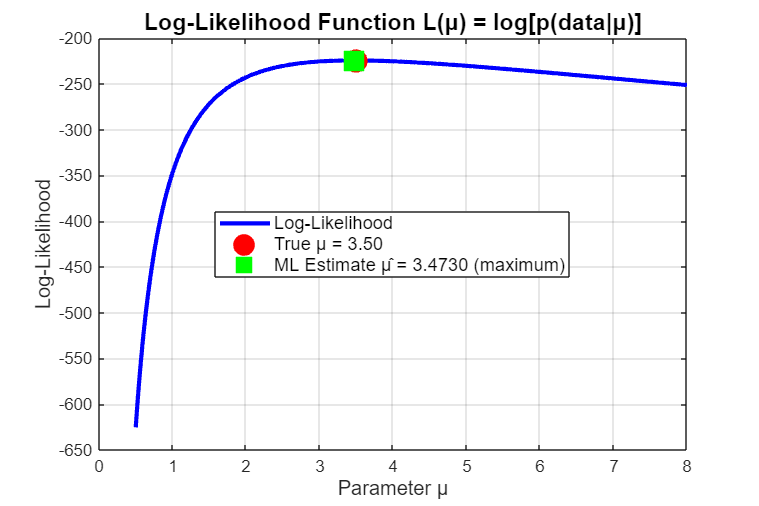


figure('Position', [200, 200, 900, 600]);
mu_range = linspace(0.5, 8, 500);
log_likelihood = zeros(size(mu_range));

for i = 1:length(mu_range)
    mu_test = mu_range(i);
    log_likelihood(i) = -N*log(mu_test) - sum(V)/mu_test;
end

plot(mu_range, log_likelihood, 'b-', 'LineWidth', 2.5);
hold on;

plot(mu_true, -N*log(mu_true) - sum(V)/mu_true, 'ro', ...
    'MarkerSize', 12, 'MarkerFaceColor', 'r', 'LineWidth', 2);

plot(mu_ML, -N*log(mu_ML) - sum(V)/mu_ML, 'gs', ...
    'MarkerSize', 14, 'MarkerFaceColor', 'g', 'LineWidth', 2);

title('Log-Likelihood Function L(μ) = log[p(data|μ)]', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Parameter μ', 'FontSize', 12);
ylabel('Log-Likelihood', 'FontSize', 12);
legend('Log-Likelihood', ...
    sprintf('True μ = %.2f', mu_true), ...
    sprintf('ML Estimate μ̂ = %.4f (maximum)', mu_ML), ...
    'FontSize', 11, 'Location', 'best');
grid on;
box on;


figure('Position', [300, 300, 900, 600]);
N_values = [5, 10, 20, 50, 100, 200, 500, 1000];
num_trials = 1000; 
estimates = zeros(length(N_values), num_trials);

for idx = 1:length(N_values)
    N_test = N_values(idx);
 
    for trial = 1:num_trials
        U_test = rand(1, N_test);
        V_test = -mu_true * log(U_test);
        estimates(idx, trial) = mean(V_test);  
    end
    
    bias = mean(estimates(idx, :)) - mu_true;
    variance = var(estimates(idx, :));
    mse = bias^2 + variance;
    
    fprintf('N = %4d:  Bias = %7.4f,  Variance = %7.4f,  MSE = %7.4f\n', ...
        N_test, bias, variance, mse);
end

N =    5:  Bias = -0.0677,  Variance =  2.3067,  MSE =  2.3112
N =   10:  Bias =  0.0516,  Variance =  1.4188,  MSE =  1.4215
N =   20:  Bias = -0.0299,  Variance =  0.6109,  MSE =  0.6118
N =   50:  Bias = -0.0010,  Variance =  0.2508,  MSE =  0.2508
N =  100:  Bias = -0.0067,  Variance =  0.1198,  MSE =  0.1199
N =  200:  Bias =  0.0020,  Variance =  0.0553,  MSE =  0.0553
N =  500:  Bias = -0.0068,  Variance =  0.0211,  MSE =  0.0211
N = 1000:  Bias =  0.0040,  Variance =  0.0124,  MSE =  0.0124


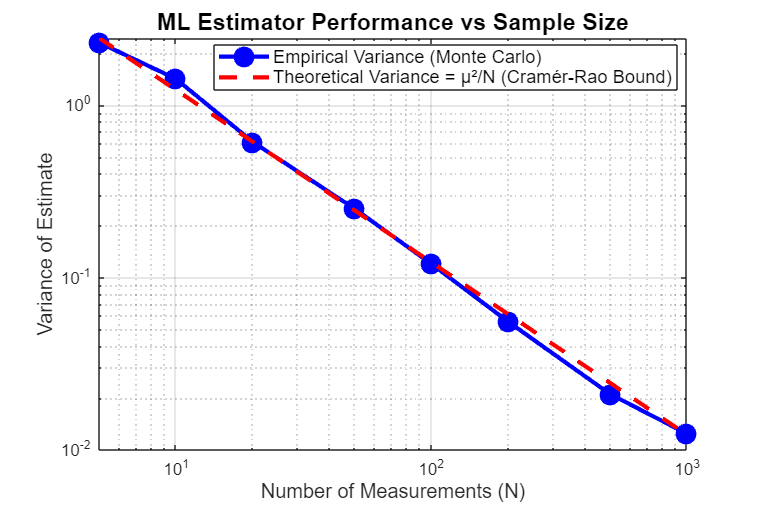



mse_values = var(estimates, 0, 2);  
plot(N_values, mse_values, 'bo-', 'LineWidth', 2.5, 'MarkerSize', 10, 'MarkerFaceColor', 'b');
hold on;

theoretical_var = (mu_true^2) ./ N_values;
plot(N_values, theoretical_var, 'r--', 'LineWidth', 2.5);

title('ML Estimator Performance vs Sample Size', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Number of Measurements (N)', 'FontSize', 12);
ylabel('Variance of Estimate', 'FontSize', 12);
legend('Empirical Variance (Monte Carlo)', ...
    'Theoretical Variance = μ²/N (Cramér-Rao Bound)', ...
    'FontSize', 11, 'Location', 'best');
grid on;
box on;
set(gca, 'XScale', 'log', 'YScale', 'log');

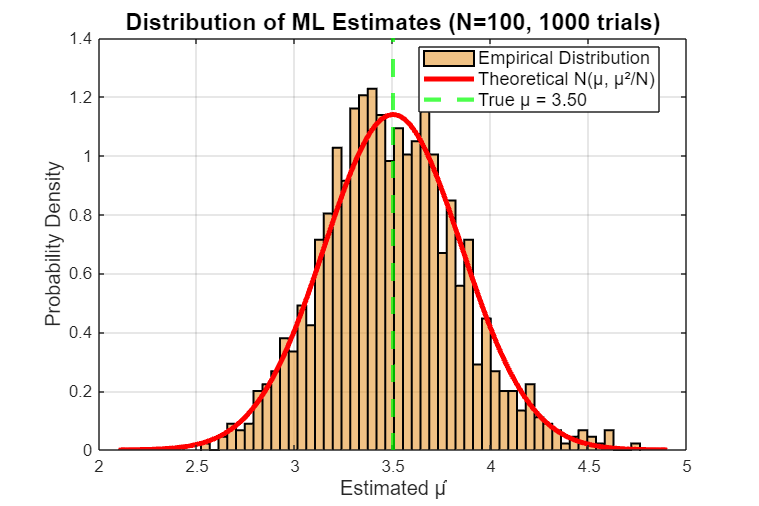


figure('Position', [400, 400, 900, 600]);

idx_100 = find(N_values == 100);
estimates_100 = estimates(idx_100, :);

histogram(estimates_100, 50, 'Normalization', 'pdf', ...
    'FaceColor', [0.9 0.6 0.2], 'EdgeColor', 'black', 'LineWidth', 1.2);
hold on;

mu_hat_mean = mu_true;
mu_hat_std = mu_true / sqrt(100);
x_theory = linspace(mu_hat_mean - 4*mu_hat_std, mu_hat_mean + 4*mu_hat_std, 500);
y_theory = (1/(mu_hat_std*sqrt(2*pi))) * exp(-(x_theory - mu_hat_mean).^2 / (2*mu_hat_std^2));
plot(x_theory, y_theory, 'r-', 'LineWidth', 3);

xline(mu_true, 'g--', 'LineWidth', 2.5);

title('Distribution of ML Estimates (N=100, 1000 trials)', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Estimated μ̂', 'FontSize', 12);
ylabel('Probability Density', 'FontSize', 12);
legend('Empirical Distribution', ...
    sprintf('Theoretical N(μ, μ²/N)'), ...
    sprintf('True μ = %.2f', mu_true), ...
    'FontSize', 11, 'Location', 'best');
grid on;
box on;


mean_est = mean(estimates_100);
std_est = std(estimates_100);

fprintf('   True parameter:     μ = %.2f\n', mu_true);

   True parameter:     μ = 3.50


fprintf('   ML estimate (N=%d): μ̂ = %.4f\n', N, mu_ML);

   ML estimate (N=100): μ̂ = 3.4730


fprintf('   Error:              %.2f%%\n\n', 100*abs(mu_ML - mu_true)/mu_true);

   Error:              0.77%



% 5.


a_true = 2.5;     
sigma_true = 0.8;  
N = 10;            
fprintf('  Slope: a = %.2f\n', a_true);

  Slope: a = 2.50


fprintf('  Noise Std Dev = %.2f\n', sigma_true);

  Noise Std Dev = 0.80


fprintf('  Number of measurements: N = %d\n\n', N);

  Number of measurements: N = 10




x = linspace(0, 5, N)';
noise = sigma_true * randn(N, 1);
y = a_true * x + noise;
fprintf('Measurement Pairs (x_i, y_i):\n');

Measurement Pairs (x_i, y_i):


fprintf('     x         y      (True: y=%.2f*x)\n', a_true);

     x         y      (True: y=2.50*x)


fprintf('------   --------\n');

------   --------


for i = 1:N
    fprintf('%7.3f  %8.3f\n', x(i), y(i));
end

  0.000    -0.187
  0.556     1.234
  1.111     3.177
  1.667     4.713
  2.222     3.696
  2.778     8.010
  3.333     9.225
  3.889    10.253
  4.444    13.073
  5.000    13.111



a_ML = sum(x .* y) / sum(x.^2);
residuals = y - a_ML * x;
sigma2_ML = (1/N) * sum(residuals.^2);
sigma_ML = sqrt(sigma2_ML);

fprintf('  ML Estimate of slope:     = %.4f\n', a_ML);

  ML Estimate of slope:     = 2.6922


fprintf('  True slope:              a = %.2f\n', a_true);

  True slope:              a = 2.50


fprintf('  Estimation error:         = %.4f (%.2f%%)\n\n', ...
    abs(a_ML - a_true), 100*abs(a_ML - a_true)/a_true);

  Estimation error:         = 0.1922 (7.69%)




fprintf('  ML Estimate of noise Std Dev:  = %.4f\n', sigma_ML);

  ML Estimate of noise Std Dev:  = 0.8462


fprintf('  True noise Std Dev:             = %.2f\n', sigma_true);

  True noise Std Dev:             = 0.80


fprintf('  Error:                         = %.4f (%.2f%%)\n\n', ...
    abs(sigma_ML - sigma_true), 100*abs(sigma_ML - sigma_true)/sigma_true);

  Error:                         = 0.0462 (5.77%)




SS_residual = sum(residuals.^2);
SS_total = sum((y - mean(y)).^2);
R_squared = 1 - SS_residual / SS_total;

fprintf('  Residual Sum of Squares: %.4f\n\n', SS_residual);

  Residual Sum of Squares: 7.1604



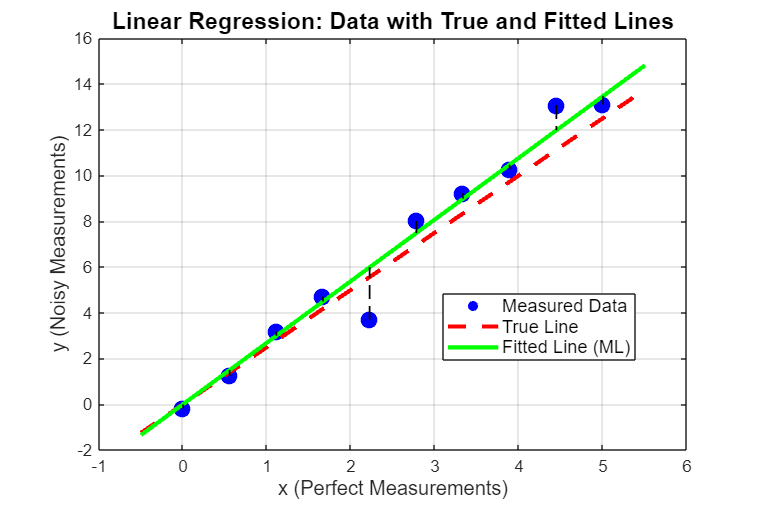



figure('Position', [100, 100, 900, 600]);

scatter(x, y, 100, 'bo', 'filled', 'LineWidth', 1.5);
hold on;

x_line = linspace(min(x)-0.5, max(x)+0.5, 100);
y_true_line = a_true * x_line;
plot(x_line, y_true_line, 'r--', 'LineWidth', 2.5, 'DisplayName', sprintf('True: y=%.2f·x', a_true));

y_fitted_line = a_ML * x_line;
plot(x_line, y_fitted_line, 'g-', 'LineWidth', 2.5, 'DisplayName', sprintf('ML Estimate: y=%.4f·x', a_ML));

for i = 1:N
    plot([x(i), x(i)], [y(i), a_ML*x(i)], 'k--', 'LineWidth', 1);
end

title('Linear Regression: Data with True and Fitted Lines', ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('x (Perfect Measurements)', 'FontSize', 12);
ylabel('y (Noisy Measurements)', 'FontSize', 12);
legend('Measured Data', 'True Line', 'Fitted Line (ML)', 'FontSize', 11, 'Location', 'best');
grid on;
box on;

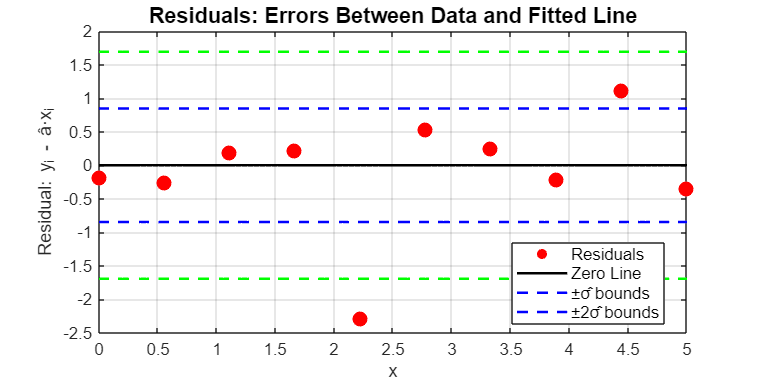


figure('Position', [200, 200, 1000, 500]);

hold on;
scatter(x, residuals, 80, 'ro', 'filled', 'LineWidth', 1.5);

plot(linspace(min(x), max(x), 100), zeros(100, 1), 'k-', 'LineWidth', 1.5);

plot(linspace(min(x), max(x), 100), sigma_ML*ones(100, 1), 'b--', 'LineWidth', 1.5);
plot(linspace(min(x), max(x), 100), -sigma_ML*ones(100, 1), 'b--', 'LineWidth', 1.5);

plot(linspace(min(x), max(x), 100), 2*sigma_ML*ones(100, 1), 'g--', 'LineWidth', 1.5);
plot(linspace(min(x), max(x), 100), -2*sigma_ML*ones(100, 1), 'g--', 'LineWidth', 1.5);

title('Residuals: Errors Between Data and Fitted Line', 'FontSize', 13, 'FontWeight', 'bold');
xlabel('x', 'FontSize', 11);
ylabel('Residual: y_i - â·x_i', 'FontSize', 11);
legend('Residuals', 'Zero Line', '±σ̂ bounds', '±2σ̂ bounds', 'FontSize', 10, 'Location', 'best');
grid on;
box on;
hold off;

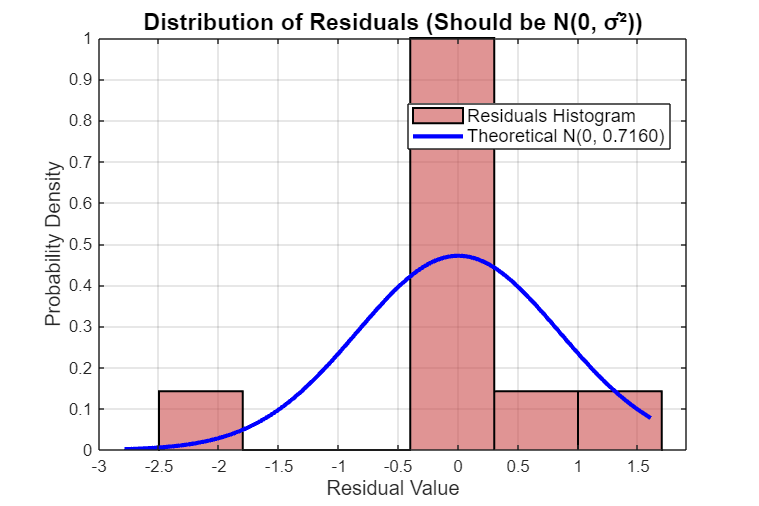


figure('Position', [300, 300, 900, 600]);

histogram(residuals, 6, 'Normalization', 'pdf', 'FaceColor', [0.8 0.3 0.3], 'EdgeColor', 'black', 'LineWidth', 1.2);
hold on;

residual_range = linspace(min(residuals)-0.5, max(residuals)+0.5, 200);
residual_pdf = (1/(sigma_ML*sqrt(2*pi))) * exp(-(residual_range).^2 / (2*sigma_ML^2));
plot(residual_range, residual_pdf, 'b-', 'LineWidth', 2.5);

title('Distribution of Residuals (Should be N(0, σ̂²))', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Residual Value', 'FontSize', 12);
ylabel('Probability Density', 'FontSize', 12);
legend('Residuals Histogram', sprintf('Theoretical N(0, %.4f)', sigma_ML^2), 'FontSize', 11, 'Location', 'best');
grid on;
box on;

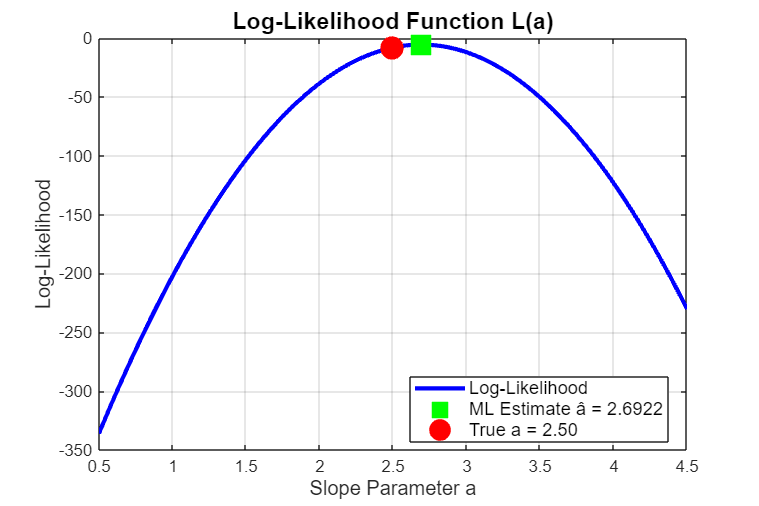


figure('Position', [400, 100, 900, 600]);

a_range = linspace(a_true - 2, a_true + 2, 200);
log_likelihood = zeros(size(a_range));

for i = 1:length(a_range)
    a_test = a_range(i);
    residuals_test = y - a_test * x;
    log_likelihood(i) = -sum(residuals_test.^2) / (2*sigma_true^2);
end

plot(a_range, log_likelihood, 'b-', 'LineWidth', 2.5);
hold on;

plot(a_ML, -sum((y - a_ML*x).^2)/(2*sigma_true^2), 'gs', ...
    'MarkerSize', 14, 'MarkerFaceColor', 'g', 'LineWidth', 2);

plot(a_true, -sum((y - a_true*x).^2)/(2*sigma_true^2), 'ro', ...
    'MarkerSize', 12, 'MarkerFaceColor', 'r', 'LineWidth', 2);

title('Log-Likelihood Function L(a)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Slope Parameter a', 'FontSize', 12);
ylabel('Log-Likelihood', 'FontSize', 12);
legend('Log-Likelihood', ...
    sprintf('ML Estimate â = %.4f', a_ML), ...
    sprintf('True a = %.2f', a_true), ...
    'FontSize', 11, 'Location', 'best');
grid on;
box on;

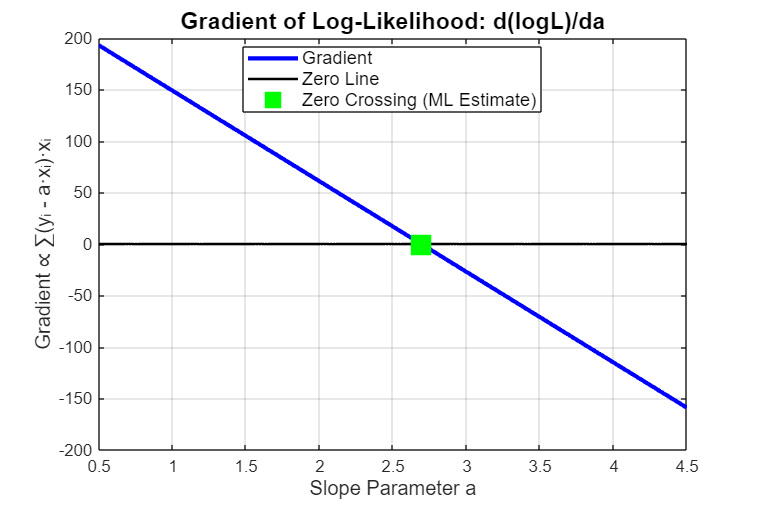


figure('Position', [500, 200, 900, 600]);

grad_a = zeros(size(a_range));
for i = 1:length(a_range)
    a_test = a_range(i);

    grad_a(i) = sum((y - a_test*x) .* x);
end

plot(a_range, grad_a, 'b-', 'LineWidth', 2.5);
hold on;

plot(a_range, zeros(size(a_range)), 'k-', 'LineWidth', 1.5);

plot(a_ML, 0, 'gs', 'MarkerSize', 14, 'MarkerFaceColor', 'g', 'LineWidth', 2);

title('Gradient of Log-Likelihood: d(logL)/da', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Slope Parameter a', 'FontSize', 12);
ylabel('Gradient ∝ ∑(yᵢ - a·xᵢ)·xᵢ', 'FontSize', 12);
legend('Gradient', 'Zero Line', 'Zero Crossing (ML Estimate)', 'FontSize', 11, 'Location', 'best');
grid on;
box on;


sum_xy = sum(x .* y);
sum_x2 = sum(x.^2);
sum_x = sum(x);
sum_y = sum(y);


fprintf('  a^ = ∑(x_i·y_i) / ∑(x_i²)\n');

  a^ = ∑(x_i·y_i) / ∑(x_i²)


fprintf('    = %.4f / %.4f\n', sum_xy, sum_x2);

    = 236.8151 / 87.9630


fprintf('    = %.4f\n\n', a_ML);

    = 2.6922



fprintf('  σ̂² = (1/N) * ∑(y_i - â·x_i)²\n');

  σ̂² = (1/N) * ∑(y_i - â·x_i)²


fprintf('     = (1/%d) * %.4f\n', N, sum((y - a_ML*x).^2));

     = (1/10) * 7.1604


fprintf('     = %.4f\n\n', sigma2_ML);

     = 0.7160



fprintf('  σ̂ = %.4f\n\n', sigma_ML);

  σ̂ = 0.8462



fprintf('   â_ML = ∑(x_i·y_i) / ∑(x_i²)  (Least Squares)\n');

   â_ML = ∑(x_i·y_i) / ∑(x_i²)  (Least Squares)


fprintf('   σ̂²_ML = (1/N)·∑(y_i - â·x_i)²\n\n');

   σ̂²_ML = (1/N)·∑(y_i - â·x_i)²



fprintf('   True slope:              a = %.2f\n', a_true);

   True slope:              a = 2.50


fprintf('   ML Estimate:             â = %.4f\n', a_ML);

   ML Estimate:             â = 2.6922


fprintf('   Relative Error:          %.2f%%\n\n', 100*abs(a_ML - a_true)/a_true);

   Relative Error:          7.69%



fprintf('   True noise Std Dev:      σ = %.2f\n', sigma_true);

   True noise Std Dev:      σ = 0.80


fprintf('   ML Estimate:             σ̂ = %.4f\n', sigma_ML);

   ML Estimate:             σ̂ = 0.8462


fprintf('   Relative Error:          %.2f%%\n\n', 100*abs(sigma_ML - sigma_true)/sigma_true);

   Relative Error:          5.77%

